# Carbon Neutral

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

The challenge of climate change encourages companies, such as MathWorks, to commit themselves to become carbon neutral. This effort leads to engaging in using renewable energy to power the company's facility. In this script, we will explore two sources of renewable energy: hydropower and wind turbines. We will apply the conservation of mass, momentum, and energy to understand how this renewable energy source work and how much power it can power.

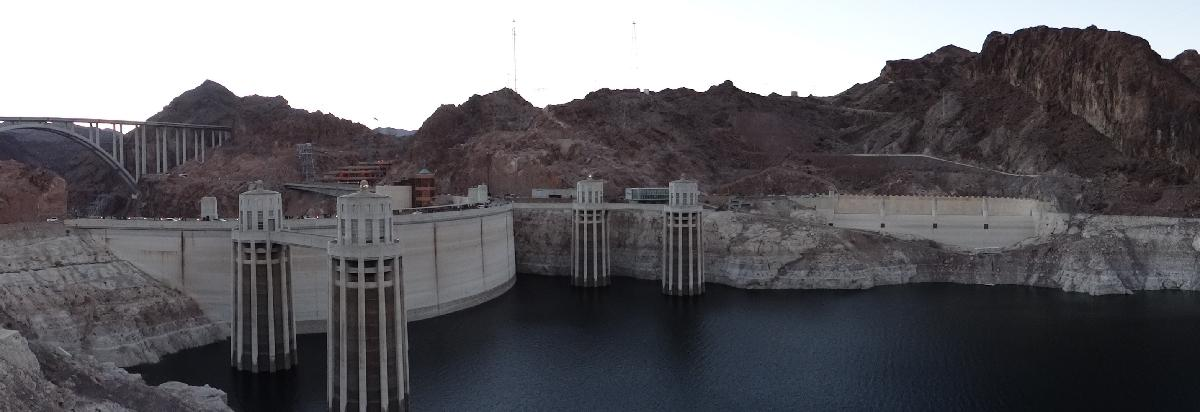

Hoover Dam intake tower from Lake Mead, [USGS](https://www.usgs.gov/media/images/hoover-dam-intake-towers-panorama)

## Energy in a fluid

In a fluid, energy refers to the ability of a fluid to produce work. It takes various form:

- Kinetic energy refers to the energy of motion.

- Potential energy refers to the energy associated external fields such as gravity.

- Internal energy refers to the molecular internal energy of the fluid.

  **Try. **Following the prompt from `unitInfo`, explore all units of energy available

unitInfo("Energy")

Just as the mass is often studied by considering the density (mass per unit of volume), we are often studying the energy in the fluid by considering the specific energy $e$ (energy per unit of mass):


$$e=\frac{V^2}{2}+gz+u$$


Where $e$ is the specific energy, $V$ is the velocity, $g$ is the local acceleration due to gravity, $z$ is the elevation and $u$ is the specific internal energy as defined in thermodynamics. If you want to learn more about internal energy, you should check out the [thermodynamics module](https://www.mathworks.com/matlabcentral/fileexchange/126784-thermodynamics). The conservation of energy can be derived the first law of thermodynamics:


$$\frac{\partial}{\partial t}\int_{CV} \rho e\; dV + \int_{CS} (\vec{V}\cdot\vec{n})\rho e\;dS=\dot{Q}-\dot{W}$$


Where $\vec{n}$ is the normal vector to the surface, $\dot{Q}$ is the rate of heat exchanged with the surrounding and $\dot{W}$ is the rate of exchanged work with the surrounding.

## Power in a fluid

Power refers to the rate at which energy is transferred, in the energy conservation equation, the term $\dot{Q}$ and $\dot{W}$ are example of powers. It is typically measured in units of energy per unit of time, such as Watts (W) or horsepower (hp).

  **Try. **Following the prompt from `unitInfo`, explore all units of pressure available

unitInfo("Power")

## Problem Statement

[PICTURE DATA CENTER XXX]

MathWorks pledged to become [carbon neutral by 2023](https://www.mathworks.com/company/aboutus/carbon-neutral.html), one of the major energy consumption of its headquarters in Natick, MA, is a data center. In this script, we will study the possibility of offsetting this power consumption by generating renewable energy with wind turbines or hydropower. We will assume that the data center’s maximum power consumption is 1300 kW. 

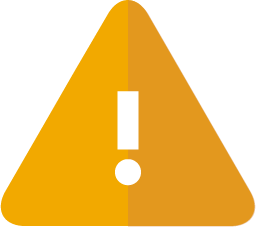 The data presented in this script are fictional and do not represent the actual power consumption by the MathWorks data center.

  **Try. **Load the data center power usage during 2022.

 
load DataCenter.mat
bar(dataCenter.date,dataCenter.avgPower)
ylabel("Average Monthly Power Consumption (kW)")
title("Data Center Power Consumption")

The previous figure presented the average power consumption by data center, we can estimate the total energy using the following relation:


$$E_\text{month} = \bar{P} \Delta{t}$$


Where $E_\text{month}$ is the power consumption during a month, $\bar{P}$ is the average power consumption during the month and $\Delta t$, in this case, is equal to a month.

 **Exercise. **Add a data entry in `dataCenter` corresponding to the total energy consumed during this month in kWh.

% Your code goes here:
dataCenter.energyUsage(:) = 0;  % Default 0

% Display the total annual energy consumption in kWh
units = symunit;
annualEnergyConsumption = sum(dataCenter.energyUsage) * units.kW*units.h

  CheckAnnualEnergyConsumpion(annualEnergyConsumption)

 **Reflect**. As a comparison, a laptop consumes around 200 kWh per year.

## Scenario 1: wind turbines

We are now considering offsetting the energy consumption calculate in the previous section by installing wind turbines near the headquarter in Natick, MA. Wind turbines generate electricity by collecting energy from incoming wind and slowing it down.

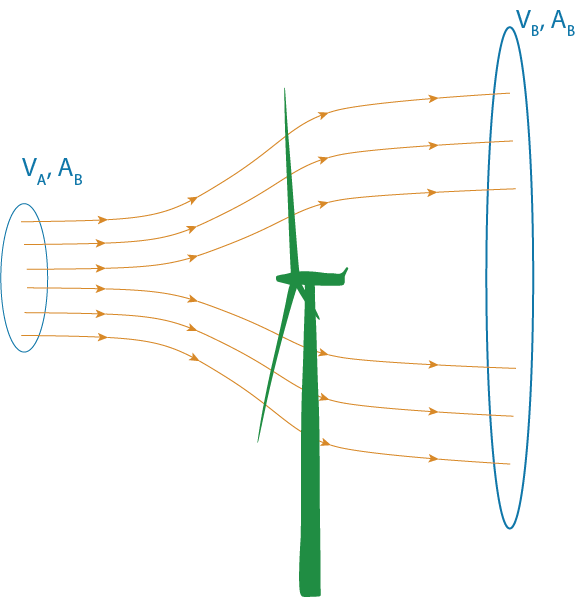

A power turbine with surface area $S_T$, generates power by collecting the kinetic energy from upstream air flow at velocity $V_A$ (m/s). The air flow is slowed down and exits the system downstream at velocity $V_B$. The wind speed at the turbine is $V_T$. 

### **Control Volume Method**

In this section, we are applying the [control volume method](matlab:open('./ManOnTheMoon.mlx')) to the wind turbine. We are considering the control volume to include all the streamlines of fluid going through the turbine from the upstream disk A to the downstream disk B introduced in the previous figure.

#### **Mass Conservation**

All the mass flow coming in the control volume through the surface A, must exit the control volume through surface B. Therefore, we can write the following mass flow equilibrium:


$$\rho S_A V_A = \rho S_B V_B = \rho S_T V_T = \dot{m}$$


where $\rho$ is the density, $(S_A,S_B,S_t)$ are the areas of surfaces A, B and the turbine, and $(V_A,V_B,V_t)$ are the velocities of the flow through the corresponding surfaces.

  **Try. **Define the problem parameters (velocities, areas) and compute the mass flow through the turbine.

syms rho_Air S_A S_B S_T V_A V_B V_T
massFlow = 0 % Default 0

#### **Momentum Conservation**

The momentum conservation equation can be expressed as:


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho\vec{u} \; dV}_\text{Acceleration}
+
\underbrace{\int_{CS}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS}_\text{Thrust}
=
\sum\vec{F}$$


We are considering the flow to be at steady-state, so the derivative with respect to time is equal to zero. There is no radial flow, so all the air entering the turbine upstream is exiting the turbine downstream. Therefore, we are left with:


$$\int_\text{upstream}(\vec{v_A}\cdot\vec{n_A})\rho\vec{v_A} \; dS
+
\int_\text{downstream}(\vec{v_B}\cdot\vec{n_B})\rho\vec{v_B} \; dS
=
\vec{F}_\text{turbine\rightarrow air}$$


We are considering that the problem is one-dimensional along the horizontal axis:


$$\int_\text{upstream}(\vec{v_A}\cdot\vec{n_A})\rho v_A \; dS
+
\int_\text{downstream}(\vec{v_B}\cdot\vec{n_B})\rho v_B \; dS
=
F_\text{turbine\rightarrow air}$$


The upstream term can be expressed as:


$$\int_\text{upstream}(\vec{v}\cdot\vec{n})\rho v \; dS
=
-\dot{m}v_A$$


 **Exercise. **Compute the expression of the force acting on the air from the turbine and its reciprocal.

% Your code goes here:
forceTurbineOnAir = 0; % Default 0

% Simplify the expression:
forceAirOnTurbine = - forceTurbineOnAir;
if (forceTurbineOnAir ~= 0)
    forceAirOnTurbine = simplify(forceAirOnTurbine)
end

  checkForceAirOnTurbine(forceAirOnTurbine)

Based on the force that the air is applying on the turbine we can define the elemental amount of work collected by the turbine as:


$$\delta W = F_{\text{air}\rightarrow\text{turbine}} \delta x$$


The power being the rate at which this work is collected we can derive its expression as follow:


$$P_\text{air\rightarrow turbine}=\frac{\delta W}{\delta t} = \frac{d(F_\text{air\rightarrow turbine}dx)}{dt}= F_\text{air\rightarrow turbine}\frac{\delta x}{\delta t}$$


Thus,


$$P_\text{air\rightarrow turbine}=F_\text{air\rightarrow turbine}V_T$$


 **Exercise. **Compute the power of the collected by the turbine.

powerCollected = 0;

  checkPowerCollected(powerCollected)

#### Energy conservation

Finally, we can consider the energy conservation equation:


$$\frac{\partial}{\partial t}\int_{CV} \rho e\; dV + \int_{CS} (\vec{u}\cdot\vec{n})\rho e\;dS=\dot{Q}-\dot{W}$$


Where, $e$ is the specific energy, $\dot{Q}$ is the rate of thermal energy brought to the system and $\dot{W}$ is the rate of work. In our case, the system is considered at steady-state and there is no thermal energy brought to the system, so $\dot{Q}=0$ and therefore:


$$ \int_{CS} (\vec{u}\cdot\vec{n})\rho e\;dS=-\dot{W}_{\text{air}\rightarrow\text{turbine}}$$


The control volume only has fluid entering through disk A and exiting through disk B, therefore:


$$P_\text{air\rightarrow turbine} = P_A - P_B \quad\quad (\clubsuit)$$


With:


$$P_{A|B} = \int_{CV} \pm V_{A|B}\; \rho e \; dS$$


The specific energy can be expressed as:


$$e = \frac{V^2}{2} + gz + u$$


In our case, we are estimating that the potential energy and internal energy stays constant from disk A to disk B and those components balance each other. Therefore, we can estimate the specific energy by only considering the kinetic energy:


$$e \approx\frac{V^2}{2}$$


Thus,


$$P_{A|B} = \pm\frac{1}{2}\dot{m}V_{A|B}^2$$


 **Exercise. **Compute the expression of the power available at disk A and disk B.

% Your code goes here:
powerA = 0;
powerB = 0;

 checkPowerAB(powerA, powerB)

 **Exercise. **Write $(\clubsuit)$ in p`owerBalance.`

powerBalance = 0==0;  % 0 == 0 default

 checkPowerBalance(powerBalance)

 **Exercise. **Solve the power balance $(\clubsuit)$ to find $V_T$ as a function of $V_A$ and $V_B$.

velocitySoln = 0;  % 0 default
 checkVelocitySoln(velocitySoln)

 **Exercise. **Substitute $V_T$ for its correct solution function of $V_A$ and $V_B$ in the expression of the power of the air on the turbine

% Select the correct answer:
if velocitySoln ~= 0
    realVelocitySoln = velocitySoln(2);
end
realVelocitySoln
% Your code goes in the next line:
powerCollected = 0;  % default 0

 checkPowerCollected2(powerCollected)

The power collected by the turbine is now a function of the upstream and downstream velocity.

### Wind turbine efficiency

The efficiency can be expressed as the ratio in between the power collected by the turbine over the maximum power available to the turbine $\eta = \frac{P_\text{turbine }}{P_\text{max}}$. The maximum available to the turbine should be equal to the power of the wind going to the surface of turbine if the turbine was not even built.

 **Exercise. **Define the maximum power that is available to the wind turbine.

% Your code goes here:
Power_max = 0; % default 0
 
 checkMaximumPower(Power_max)

 **Exercise. **Define the efficiency of the wind turbine.

% Your code goes here:
eta_turbine = 0; % default 0

 checkTurbineEta(eta_turbine)

The power efficiency of the wind turbine only depends on two parameters, the upstream and downstream velocity. However, we also know that the downstream velocity is necessarily lower than the upstream velocity and both velocities are greater than zero. Therefore, we can study the efficiency of the turbine as a function of a parameter $x = \frac{V_\text{downstream}}{V_\text{upstream}}$, the ratio of velocity in between the downstream and upstream velocity. This parameter represents how much the air flow is slowed down by the wind turbine.

  **Try. **Run the following lines of code to express the efficiency of the turbine as a function of the parameter $x$.

syms x
eta_turbine = simplify(subs(eta_turbine, V_B, x*V_A))

  **Try. **Plot the wind turbine efficiency as a function of parameter $x$.

% Plotting function
fplot(100*x,100*eta_turbine,[0 1])
xlabel("x (%)")
ylabel("\eta (%)")
title("Wind turbine efficiency")

 **Reflect**. It has a maximum, it is below one, so we can't collect the whole power coming from the upstream wind.

  **Try.** What is the maximum efficiency?

deta = diff(eta_turbine,x);
xmax = solve(deta == 0,x)
if xmax~=0
    xmax = xmax(2)
end

eta_max = subs(eta_turbine,x,xmax)

 **Reflect**. The equation presents two roots, one maximum at $x = 1/3$ for and efficiency just below 60%. The second root is $x=-1$, what would it mean physically? Is it possible?

### Estimate impact of wind turbine farm

We just computed the maximum functioning efficiency of a wind turbine. We would like to estimate how much energy could be collected in a specific location. We retrieve data from a [connected weather station](https://www.mathworks.com/matlabcentral/fileexchange/47049-analyzing-weather-data-from-an-arduino-based-weather-station?s_tid=srchtitle_weather%20station_1) in Natick, MA. Now that we know how much energy can be extracted by a wind turbine, $\eta_{\text{max}}$, we can use the Natick wind data to determine the energy that could potentially be collected by a wind turbine in this location.

  **Try.** Load and visualize the weather data.

 
load NatickWeather.mat
weather

  **Try.** Use the following slider to define the rotor span of the wind turbine, you could find some reference online.

turbineWingSpan = 45* units.meter;
S_turbine = pi*turbineWingSpan^2/4;
rho_air = 1.14*units.kg/units.meter^3;

The maximum efficiency for a wind turbine computed in the previous section was just below 60%. This efficiency is not considering the electrical and mechanical efficiency of the system. In fact, most wind turbine function at lower efficiency than the ideal maximum efficiency we defined. For the rest of this script, we will consider that the global efficiency of the system is $\eta = 40\%$. The power maximum power to be extracted from the wind can be estimated as:


$$P_{max}=\frac{1}{2}\rho S_t V^3$$


and, 


$$\eta = \frac{P_\text{collected}}{P_{max}}$$


 **Exercise. **Using the dot notation, add a column to the weather table corresponding the the power extracted from the wind with a 40% efficient wind turbine. 

% Define the efficiency:
eta = 0.4;

% Your code goes here:
weather.powerCollected(:) = 0;

  checkPowerExtractedTurbine(weather,turbineWingSpan)

  **Try.** Based on your previous answer, we can compute the energy that is generated each day, the annual energy production and so the number of wind turbine that would need to be installed to power the data center.

% Compute the daily and annual energy produced by the wind turbine
weather.dailyProduction = weather.powerCollected * 1*units.day;
turbineAnnualProduction = sum(weather.dailyProduction)
if turbineAnnualProduction ~= 0
    % Rewrite this energy in more common enregy unit, kWh
    turbineAnnualProduction = vpa(rewrite(turbineAnnualProduction, units.kWh),8)
    
    % Compute the number of wind turbine that would need to be installed
    numberOfTurbine = round(double(separateUnits(annualEnergyConsumption/turbineAnnualProduction)),0)
end

 **Reflect**. How acceptable would it be to install this number of wind turbines in a suburban area such as Natick, MA?

## Scenario 2: Hydropower

The second option considered to power the MathWorks' data center is to build a retention lake nearby the headquarter in Natick, MA. The water collected in this retention lake would be used to generate hydroelectricity. We are considering building a retention lake inspired by [MATLAB logo](https://www.mathworks.com/help/matlab/visualize/creating-the-matlab-logo.html).

  **Try. **Visualize the design of the retention lake.

 
plotRetentionLake

### Creating a mathematical model

To model the power generated over a year by this installation, we are going to apply the conservation of mass to the control volume that is the lake. 


$$\displaystyle\frac{\partial}{\partial t}\int_{CV}\rho \; dV+\int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$



$$\displaystyle\frac{\partial}{\partial t}\int_{CV}\rho S_\text{lake} \; dh + \int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$



$$\rho S_\text{lake}\frac{dh}{dt} + \int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$



$$\rho S_\text{lake}\frac{dh}{dt} + \dot{m}_\text{rain} + \dot{m}_\text{evaporation} + \dot{m}_\text{turbine} = 0$$


To assure the sustainability of the water resource, we will require that the retention lake constantly keep the same water height, therefore  $\frac{dh}{dt} = 0$, and:


$$\dot{m}_\text{turbine} = - \dot{m}_\text{rain} - \dot{m}_\text{evaporation}$$


**Remark: **The different $\dot{m}$ are positive if the flow is leaving the control volume (*i.e. *the retention lake) and negative if the flow is entering the control volume. We can abandon that convention and consider all the mass flows as positive. Then the previous equation becomes:


$$\dot{m}_\text{turbine} =  \dot{m}_\text{rain} - \dot{m}_\text{evaporation}$$


This equation describes that the mass flow through the turbine is equal to the mass flow received from the rain minus the mass flow of water evaporated. We are considering that the rain and evaporation mass flow are only dependent of the local weather and the dimensions of the retention lake. 

  **Try.** Define the parameters of the problem:

-  `lakeLength` represents the side length of the lake, 

- `surfaceLake` represents the surface area of the lake, 

- `rhoWater` is the density of water in the lake, 

- `deltaH` is the elevation difference between the surface of the lake and the turbine, 

- basinArea represents the surface from which rainwater is captured for the retention lake.

 
lakeLength = 100*units.m;
surfaceLake = lakeLength^2;
rhoWater = 1000*units.kg/units.m^3;
deltaH = 10*units.m;
basinArea = 1*units.km^2;

#### Modeling the rainfall

The water collected from the rainfall is modelled using real data collected from a custom weather station installed on one of the parking garages at the MathWorks Apple Hill campus in Natick, Massachusetts.

  **Try.** Load and visualize the weather data.

 
load NatickWeather.mat
weather

In this table, the temperature is reported in degrees Celsius, the wind in meters per second, the relative humidity is in percent, the rainfall is in millimeters and the dew point is in degrees Celsius.

 **Exercise. **Using the dot operator, add a column to the table that represents the mass of water accumulating in the lake from the rainfall during each day, do not forget to assign a unit to the rainfall.

% Your code goes here:
weather.dailyMassRain(:) = 0;

% Show the annual rainfall in Natick in term of mass:
annualMassRain = sum(weather.dailyMassRain);
if annualMassRain ~= 0
    annualMassRain = simplify(sum(weather.dailyMassRain))
end

  checkAnnualRain(annualMassRain)

#### Model the evaporation

The evaporation of the lake is a function of the temperature, wind speed and relative humidity of the air. 


$$\dot{m}_\text{evaporation} = (\alpha+\beta V_\text{wind})S_\text{lake}(W_s-W)$$


- 
$$\alpha = 600\;\text{kg}\cdot\text{m}^{-2}$$
 

- 
$$\beta=455 \;\text{kg}\cdot\text{m}^{-3}\cdot\text{s}$$


$W$ and $W_s$ are the humidity ratio and the maximum humidity ratio defined by the following formula:


$$W = 0.62198 \frac{P_w}{P-P_w}$$



$$W_s = 0.62198\frac{P_s}{P-P_s}$$


where $P$ is the atmospheric pressure, consider to be equal to 101325 Pa, $P_w$ is the partial pressure of water in the air, and $P_s$ is the saturation pressure of water. The saturation pressure can be approximated using Antoine's equation:


$$\log_{10}(P_s) = A - \frac{B}{C+T}$$


- 
$$A=8.07131$$


- 
$$B=1730.63$$


- 
$$C=233.426$$
 

When using Antoine's equation, one must be careful with the units as the temperature is in degrees Celsius and the saturation pressure is in millimeters of mercury (mmHg).

 **Exercise. **Compute the saturation pressure based on Antoine's equation, don't forget to include the units!

% Antoine's equation parameters:
A = 8.07131;
B = 1730.63;
C = 233.426;

% Your code goes here:
weather.saturationPressure(:) = 0;

% Answer check/hints:
 checkSaturationPressure(weather)

The partial pressure of water in the air can be computed using the following relation:


$$RH = \frac{P_w }{ P_s}$$


 **Exercise. **Compute the partial pressure of water in the air.

% Your code goes here
weather.waterPressure(:) = 0;

% Answer check/hints:
 checkWaterPressure(weather)

  **Try.  **Compute $W$ and $W_s$ are the humidity ratio and the maximum humidity ratio.

weather.W = simplify(0.62198*weather.waterPressure./(101325*units.Pa-weather.waterPressure));
weather.Ws = simplify(0.62198*weather.saturationPressure./(101325*units.Pa-weather.waterPressure));

The mass flow of water lost due to evaporation can now be estimated using the following relation:


$$\dot{m}_\text{evaporation} = (25+19 V_\text{wind})S_\text{lake}(W_s-W)$$


  **Try. **Compute the total energy that could be generated from this retention lake

weather.massEvaporation = units.kg/units.m^2*(600+455*weather.Wind).*surfaceLake.*(weather.Ws-weather.W);
totalWaterEvaporated = sum(weather.massEvaporation)

  **Try. **Compute the total energy that could be generated from this retention lake.

totalWaterAvailable = annualMassRain - totalWaterEvaporated  % Total water available to produce energy
totalEnergy = rewrite(totalWaterAvailable*10*units.mH2O, [units.kWh])/rhoWater % Total Energy that could be produced
ratio = totalEnergy / annualEnergyConsumption % Ratio of the annual consumption that would be covered

 **Reflect**. How acceptable would it be to create a retention lake near residential area to only power a small fraction of the data center?

## Further exploration

Explore examples of demonstrating MATLAB and Simulink uses to [model renewable energy sources](https://www.mathworks.com/company/newsletters/articles/developing-renewable-energy-technologies-to-mitigate-climate-change-using-matlab-and-simulink.html?s_tid=srchtitle_wind_9):

- [Solar cell](https://www.mathworks.com/help/releases/R2023a/sps/ug/solar-cell-power-curve.html)

- [Wind turbine](https://www.mathworks.com/help/releases/R2023a/sps/ug/wind-turbine.html)

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

## Helper Functions

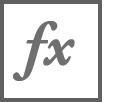`CheckAnnualEnergyConsumpion(annualEnergyConsumption)`

function CheckAnnualEnergyConsumpion(annualEnergyConsumption)
    arguments
       annualEnergyConsumption (1,1) sym 
    end

    % Compute the correct answer
    units = symunit;
    load DataCenter.mat
    dataCenter.energyUsage = dataCenter.avgPower.*dataCenter.numberOfDay*24;
    rightAnswer = sum(dataCenter.energyUsage)*units.kW*units.h;

    % Compute wrong answer if delta t was in seconds
    dataCenter.energyUsage = dataCenter.avgPower.*dataCenter.numberOfDay*24*3600;
    wrongSecond = sum(dataCenter.energyUsage)*units.kW*units.h;

    % Forgot number of hours
    dataCenter.energyUsage = dataCenter.avgPower.*dataCenter.numberOfDay;
    wrongHour = sum(dataCenter.energyUsage)*units.kW*units.h;

    % Forgot number of days
    dataCenter.energyUsage = dataCenter.avgPower.*24;
    wrongMonth = sum(dataCenter.energyUsage)*units.kW*units.h;

    % Forgot delta T
    dataCenter.energyUsage = dataCenter.avgPower;
    wrongDT = sum(dataCenter.energyUsage)*units.kW*units.h;
    
    if isequal(rightAnswer,annualEnergyConsumption)
        disp("Good job! You computed the total annual energy consumption correctly.")
    else
        if isequal(wrongSecond, annualEnergyConsumption)
            warning("Your reasoning is correct, however your unit is wrong, make sure to express the time in hours not seconds.")
        elseif isequal(wrongHour, annualEnergyConsumption)
            warning("Your reasoning is correct, however it appears that you forgot to multiply by the number of hours in a day.")
        elseif isequal(wrongMonth, annualEnergyConsumption)
            warning("Your reasoning is correct, however it appears that you forgot to multiply by the number of days in a month.")
        elseif isequal(wrongDT, annualEnergyConsumption)
            warning("You forgot to multiply the average power consumption by a unit of time. Hint: this time has to be expressed in hours.")
        else
            warning("Please complete the line of code indicated in the comment.")
        end
    end
end

`checkForceAirOnTurbine(answer)`

function checkForceAirOnTurbine(answer)
    arguments
        answer (1,1) sym
    end
    
    % Define the solution
    syms rho_Air V_T S_T V_A V_B
    massFlow = rho_Air*V_T*S_T;
    solution =  simplify(massFlow*V_A - massFlow*V_B);
    
    if isequal(answer, solution)
        disp("Good job! You define the force applied by the air on the turbine correctly!")
    else
        if isequal(answer, -solution)
            warning("Your reasoning is correct, however you are comitting a sign error.")
        else
            warning("There is an error in your computation. Hint: while the integral over"+...
                " the surface A resulted in a negative sign, the integral over surface B should"+...
                " results in a positive sign.")
        end
    end

end

`checkPowerAB(answerA,answerB)`

function checkPowerAB(answerA,answerB)
    arguments
        answerA (1,1) sym
        answerB (1,1) sym
    end
    
    syms rho_Air S_A S_B S_T V_A V_B V_T
    rightAnswerA = 1/2*rho_Air*S_T*V_T*V_A^2;
    rightAnswerB = 1/2*rho_Air*S_T*V_T*V_B^2;

    if ~isequal(answerA,rightAnswerA)
        warning("You should expressed the power at point A as a function of"+...
            " the mass flow and velocity at point A.")
    end
    if ~isequal(answerB,rightAnswerB)
        warning("You should expressed the power at point B as a function of"+...
            " the mass flow and velocity at point B.")
    end
    
    if isequal(answerA,rightAnswerA) && isequal(answerB,rightAnswerB)
        disp("Good job! You defined the power at points A and B correctly.")
    end

end

`plotRetentionLake()`

function plotRetentionLake()
    Z = membrane(1,10);
    Z = [[fliplr(Z) Z]; flipud([fliplr(Z) Z])];
    n = size(Z,1);
    [X,Y] = meshgrid(0:n-1,0:n-1);
    X = 2*X/(n-1) - 1;
    Y = 2*Y/(n-1) - 1;
    C = zeros(size(Z));
    C(11:31,11:31) = 1.0;
    Z(1,:) = 0.0;
    Z(end,:) = 0.0;
    Z(:,1) = 0.0;
    Z(1,end) = 0.0;
    Z( Z < 0 ) = 0.0;
    X = X * 100;
    Y = Y * 100;
    s = surf(X,Y,Z,C,"FaceColor","flat","EdgeColor","k");
    view([-64 59])
    mapFace = [0.3 0.3 0.3
               0.83 0.94 0.97];
    colormap(mapFace)
end

`checkPowerCollected(answer)`

function checkPowerCollected(answer)
    arguments
        answer (1,1) sym
    end

    syms rho_Air S_A S_B S_T V_A V_B V_T
    rightAnswer = rho_Air*S_T*V_T^2*(V_A-V_B);

    if isequal(answer,rightAnswer)
        disp("Good job! You calculated the power collected correctly.")
    else
        warning("The power collected should be expressed as the velocity through "+...
            "the turbine mulitplied by the force acting on the turbine.")
    end
       
end

`checkPowerBalance(answer)`

function checkPowerBalance(answer)
    arguments
        answer (1,1) sym
    end

    syms rho_Air S_T V_A V_B V_T
    rightAnswer = rho_Air*S_T*V_T^2*(V_A-V_B) ==...
        1/2*rho_Air*S_T*V_A^2*V_T -...
        1/2*rho_Air*S_T*V_B^2*V_T;

    if isequal(rightAnswer,answer)
        disp("Good job! You defined the power balance correctly.")
    else
        warning("The power balance should be defined as the power collected being equal"+...
            " to the difference of the upstream and downstram power.")
    end

end

`checkVelocitySoln(answer)`

function checkVelocitySoln(answer)
    arguments
        answer (:,:) sym
    end
    syms V_A V_B
    rightAnswer = sym('r', [1; 2])';
    rightAnswer(1) = 0;
    rightAnswer(2) = 1/2*(V_A+V_B);

    if isequal(answer,rightAnswer)
        disp("Good job! You found demonstrated that the velocity through the turbine is the "+...
            "average of the upstream and downstream velocity.")
    else
        warning("Hint: use the function solve!")
    end

end

`checkPowerCollected2(answer)`

function checkPowerCollected2(answer)
    arguments
        answer (1,1) sym
    end

    syms rho_Air S_T V_A V_B V_T
    rightAnwer = rho_Air*S_T*(1/2*V_A+1/2*V_B)^2*(V_A-V_B);

    if isequal(answer,rightAnwer)
        disp("Good job! You found the expression of the power collected as a function of "+...
            "the upstream and downstream velocity.")
    else
        warning("Use the function subs to substitute the velocity of a turbine with its "+...
            "expression as a function of the upstream and downstream velocity defined in "+...
            "the previous exercise.s")
    end
end

`checkMaximumPower(answer)`

function checkMaximumPower(answer)
    arguments
        answer (1,1) sym
    end

    syms rho_Air S_T V_A
    rightAnswer = 1/2*S_T*rho_Air*V_A^3;

    if isequal(answer,rightAnswer)
        disp("Good job! You defined the maximum to be collected by the turbine correctly.")
    else
        warning("The maximum power to be collected would be the power going through the turbine "+...
            "rotor disk if the turbine was not there.")
    end

end

`checkTurbineEta(answer)`

function checkTurbineEta(answer)
    arguments
        answer (1,1) sym
    end

    syms V_A V_B eta_turbine
    rightAnswer = 1/2*(V_A+V_B)^2*(V_A-V_B)/(V_A^3);
    
    if isequal(simplify(answer),rightAnswer)
        disp("Good job! You defined the turbine efficiency correctly. The simplified form is:")
        displayFormula("eta_turbine = rightAnswer")
    else
        warning("Hint: The turbine effiency is the ratio of the power collected by the turbine "+...
            " over the maximum power to be collected.")
    end
end

`checkAnnualRain(answer)`

function checkAnnualRain(answer)
    arguments
        answer (1,1) sym
    end

    num_answer = double(separateUnits(answer));
    if 0.9*6.7475e+08 <= num_answer && num_answer <= 1.1*6.7475e+08 
        disp("Good job! The mass of annual rain was defined correctly.")
        disp("There is approximately " + num_answer + " kg of water available each year.")
    else
        warning("The mass of water can be computed as a product of the density times the volume of water.")
    end

end

`checkSaturationPressure(answer)`

function checkSaturationPressure(answer)
    rightMean = 12.3840;
    answerMean = mean(separateUnits(answer.saturationPressure));

    if 0.9*rightMean <= answerMean && answerMean <= 1.1*rightMean
        disp("Good job! The saturation pressure was defined correctly.")
    else
        warning("You can compute the saturation pressure using Antoine's"+...
            newline + " equation introduced previously")
    end
    
end

`checkWaterPressure(answer)`

function checkWaterPressure(answer)
    rightMean = 8.6823;
    answerMean = mean(separateUnits(answer.waterPressure));

    if 0.9*rightMean <= answerMean && answerMean <= 1.1*rightMean
        disp("Good job! The water pressure was defined correctly.")
    else
        warning("You can compute the water pressure based on the saturation "+...
            "pressure and the relative humdity.")
    end

end

`checkPowerExtractedTurbine(answer,wingspan)`

function checkPowerExtractedTurbine(answer,wingspan)
    
    rightMean = separateUnits(2.4603*pi*(wingspan/2)^2);
    answerMean = mean(separateUnits(answer.powerCollected));

    if 0.99*rightMean <= answerMean && answerMean <= 1.01*rightMean
        disp("Good job! The power corrected was defined correctly.")
        disp("You can extract, on average, " + double(answerMean) + " kW per day")
    else
        warning("You can compute the power extracted based on the wind speed "+...
            "and the expression developed in the previous section of this script.")
    end
end

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

Copyright 2023 The MathWorks™, Inc